clear, clc, close all

dim = 2;
n = 200;

A = -1 * ones(n, dim) + (1 - (-1)) * rand(n, dim);
b = -1 * ones(n,1) + (1 - (-1)) * rand(n, 1);

linprog([1 1], A, b)

找不到可行解。

Linprog 已停止，因为没有满足约束的点。

ans =
     []



% A = [eye(dim);
%      -eye(dim)];
% b = [ones(dim,1) * -0;
%      ones(dim,1) * -4];

% the norm of each row of A
aNorms = sqrt(sum(A.^2, 2));

% normalize, necessary since the direction vector should be of same norm
A_normd = A ./ aNorms;
b_normd = b ./ aNorms;

tic
x_star_lp = minmaxlinear(A, b)

x_star_lp =    -0.8338
   -0.9580


d = max(A * x_star_lp - b)

d = 2.3344

toc

历时 0.007214 秒。



tic
x_star_ucon = minmaxdUcon(A, b)

x_star_ucon =    -0.8338
   -0.9580


d1 = max(A * x_star_ucon - b)

d1 = 2.3344

toc

历时 0.005878 秒。



opt = optimoptions("linprog", "Display","off");
cnt = 0;
t = 0;
while true
    A = [-1 * ones(n, dim) + (1 - (-1)) * rand(n, dim)];
    b = [-1 * ones(n,1) + (1 - (-1)) * rand(n, 1)];

    % the norm of each row of A
    aNorms = sqrt(sum(A.^2, 2));

    % normalize, necessary since the direction vector should be of same norm
    A_normd = A ./ aNorms;
    b_normd = b ./ aNorms;

    [~,~,flag] = linprog([1 1], A, b, [], [], [], [], opt);

    if flag == -2 % not feasible
        tic
        % x_star = minmaxd(A, b);
        x_star = minmaxlinear(A, b);
        t1 = toc;

        tic
        x_star2 = minmaxdUcon(A, b);
        t2 = toc;

        t = t2 - t1;

        d1 = max(A_normd * x_star - b_normd);
        d2 = max(A_normd * x_star2 - b_normd);
        if (d1 - d2) > 1E-5
            x_star
            x_star2
            d1
            d2
            err = (d1 - d2)
            error("answer not equal")
        end

        cnt = cnt + 1;
        if cnt == 1E4
            break
        end
    end
end
t

t = 8.3300e-04

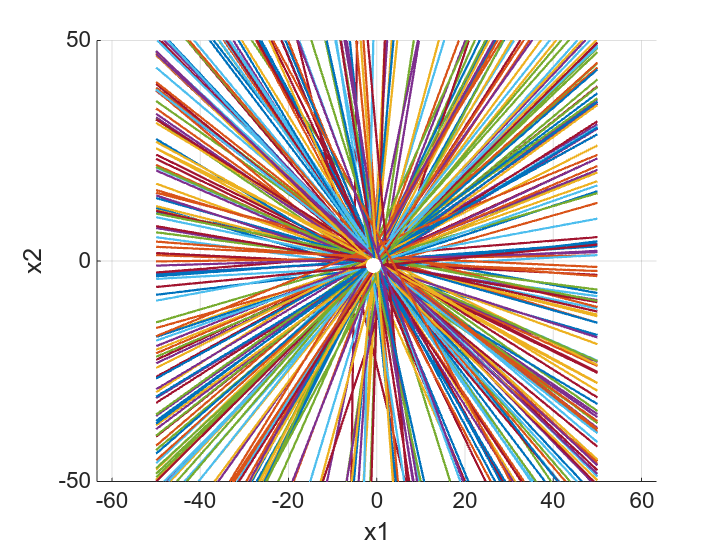



% 生成 x1 的一系列值
x1_vals = linspace(-50, 50, 400); % 这里生成 -10 到 10 之间的 400 个点

% 计算对应的 x2 值
x2_vals = (b - A(:,1) .* x1_vals) ./ A(:,2); % 对应第一个约束

% 绘制图像
figure;
hold on;
plot(x1_vals, x2_vals, 'LineWidth', 1);
plot(x_star_lp(1), x_star_lp(2), ".", "MarkerSize", 20)
plot(x_star_ucon(1), x_star_ucon(2), ".", "MarkerSize", 20, "Color", [1 1 1])

% 设置图形的属性
xlabel('x1');
ylabel('x2');
xlim([-50,50])
ylim([-50,50])
grid on;
axis equal;
% legend(["1", "2", "3"])
hold off;



function x_star = minmaxdUcon(A, b)
% the norm of each row of A
aNorms = sqrt(sum(A.^2, 2));

% normalize, necessary since the direction vector should be of same norm
A_normd = A ./ aNorms;
b_normd = b ./ aNorms;

% add a bounding box to avoid unbounded
% -M <= x_i <= M
M = 1E8;
dim = size(A,2);
A_normd = [%eye(dim);
    %-eye(dim);
    A_normd];
b_normd = [%ones(dim,1) * M;
    %ones(dim,1) * M;
    b_normd];

f = @(x) (A_normd * x - b_normd);

opt = optimoptions("fminimax", "Display","off");
x_star = fminimax(f, zeros(dim,1), [], [], [], [], [], [], [], opt);
end